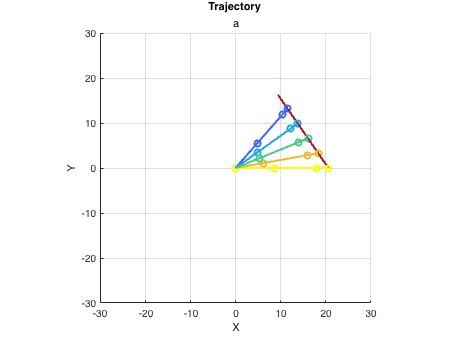

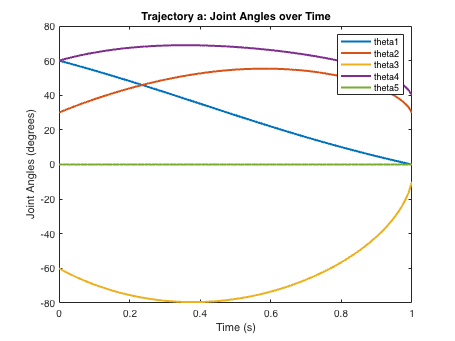

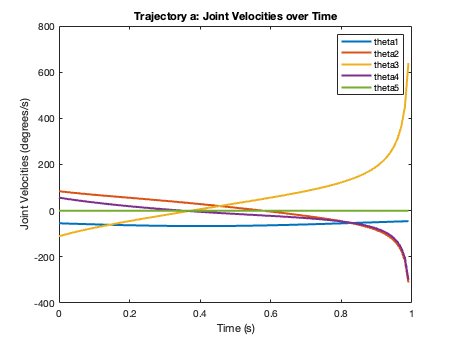

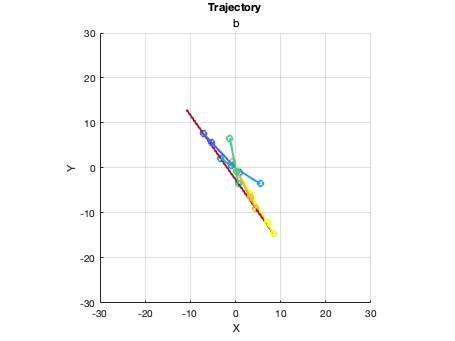

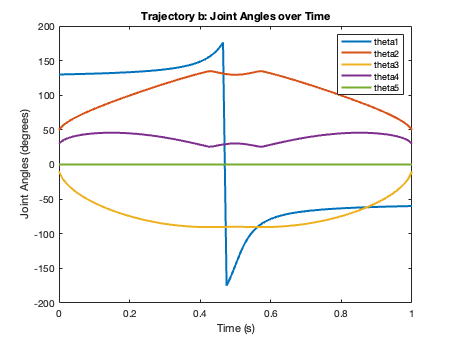

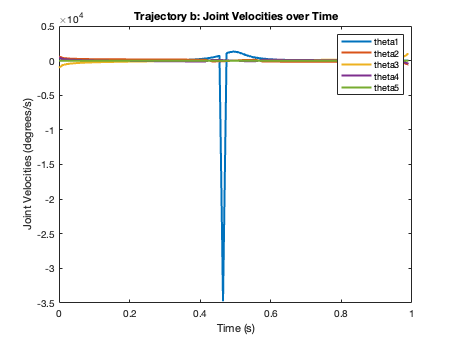

clc;
clear;
% design 5 set of theta to FK end-effecter's coordinates
theta_set1 = [60,30,-60,60,0];
theta_set2 = [-130,60,-20,50,0];
theta_set3 = [0,30,-10,40,0];
theta_set4 = [130,50,-10,30,0];
theta_set5 = [300,50,-10,30,0];

% do FK to find [x,y,z]
[xw, yw, zw, psi] = FK_LynxmotionRobot(theta_set1(1),theta_set1(2),theta_set1(3),theta_set1(4),theta_set1(5));
ee_set1 = [xw, yw, zw, psi];
[xw, yw, zw, psi] = FK_LynxmotionRobot(theta_set2(1),theta_set2(2),theta_set2(3),theta_set2(4),theta_set2(5));
ee_set2 = [xw, yw, zw, psi];
[xw, yw, zw, psi] = FK_LynxmotionRobot(theta_set3(1),theta_set3(2),theta_set3(3),theta_set3(4),theta_set3(5));
ee_set3 = [xw, yw, zw, psi];
[xw, yw, zw, psi] = FK_LynxmotionRobot(theta_set4(1),theta_set4(2),theta_set4(3),theta_set4(4),theta_set4(5));
ee_set4 = [xw, yw, zw, psi];
[xw, yw, zw] = FK_LynxmotionRobot(theta_set5(1),theta_set5(2),theta_set5(3),theta_set5(4),theta_set5(5));
ee_set5 = [xw, yw, zw, psi];


%------------------------------Trajectory a & b------------------------------
M = 100; % sample 100 points
for trajectory_abc = 1:2
    % 1.sample function to get discrete point
    if trajectory_abc == 1
        % Trajectory a (free motion): Start: set1 ; End: set3
        points = [ee_set1; ee_set3];
        trajectory_label = 'a';
    elseif trajectory_abc == 2
        % Trajectory b (straight line): Start: set1 ; End: set2
        points = [ee_set4; ee_set5];
        trajectory_label = 'b';
    end

    t = 1:size(points, 1);
    tt = linspace(1, size(points, 1), M); 
    spline_path = spline(t, points', tt); % EE's coordinates path

    % 2.apply IK calculations to get theta1-5
    joint_angles = zeros(length(tt), 5);  % Initialize matrix for joint angles

    for i = 1:length(tt)
        x = spline_path(1, i);
        y = spline_path(2, i);
        z = spline_path(3, i);
        psi = spline_path(4,i);

        % Solve for inverse kinematics
        [theta1, theta2, theta3, theta4, theta5] = IK_LynxmotionRobot(x, y, z, psi);
        joint_trajectory(i, :) = [theta1, theta2, theta3, theta4, theta5];  % Store the joint angles
    end

    % 3.Start plotting figure
    % (1) Trajectory in Cartesian Space
    figure;
    hold on;
    grid on;
    axis equal;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Trajectory ', trajectory_label);
    xlim([-30, 30]);
    ylim([-30, 30]);
    zlim([0, 30]);


    % Create a gradient of colors based on the number of points
    colors = colormap(parula(size(joint_trajectory, 1)));  % Or use 'parula' 'viridis'.

    for i = 1:size(joint_trajectory, 1)
       if mod(i, M/5) == 0 % only draw 5 senarios
            theta = joint_trajectory(i, :);
            joint_positions = Calc_JointPos(theta);
            plot3(joint_positions(:,1), joint_positions(:,2), joint_positions(:,3), '-o', ...
                   'LineWidth', 2, 'MarkerSize', 6, 'Color', colors(i, :));
            hold on;  
       end
        plot3(spline_path(1, :), spline_path(2, :), spline_path(3, :), 'LineWidth', 2);
    end


    % (2) Plot Joint Angles
    figure;
    plot(tt-1, joint_trajectory, 'LineWidth', 2);
    title(['Trajectory ', trajectory_label, ': Joint Angles over Time']);
    xlabel('Time (s)'); ylabel('Joint Angles (degrees)');
    legend('theta1', 'theta2', 'theta3', 'theta4', 'theta5');

    % (3) Calculate and Plot Joint Velocities
    joint_velocities = diff(joint_trajectory) / (tt(2) - tt(1));  % Derivative w.r.t time
    figure;
    ylim([-400, 800]);
    plot(tt(1:end-1)-1, joint_velocities, 'LineWidth', 2);
    title(['Trajectory ', trajectory_label, ': Joint Velocities over Time']);
    xlabel('Time (s)'); ylabel('Joint Velocities (degrees/s)');
    legend('theta1', 'theta2', 'theta3', 'theta4', 'theta5');
end

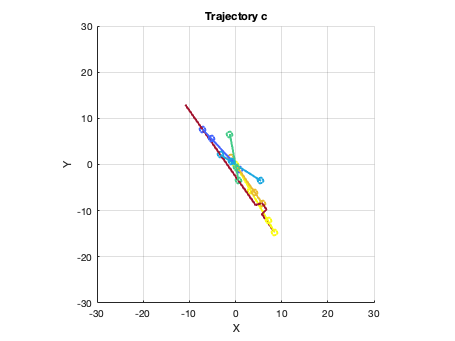


%------------------------------Trajectory c------------------------------
M = 100; % sample 100 points
% obstacle setup
obstacle_center = [5, -10, 16]; 
obstacle_radius = 1;  
obstacle_height = 1; 

% 1.sample function to get discrete point
points = [ee_set4; ee_set5];
t = 1:size(points, 1);
tt = linspace(1, size(points, 1), M); 
spline_path = spline(t, points', tt); % EE's coordinates path

% 2.Collision detection
for i = 1:size(spline_path, 2)-1
    start_point = spline_path(:, i);
    end_point = spline_path(: ,i+1);
    if isCollisionWithObstacle(start_point, end_point, obstacle_center, obstacle_radius, obstacle_height);
        spline_path(:, i) = spline_path(:, i+1) + [1, 1, 0, 0]';  % simple transform, no use of A* or other algroritm
    end
end

% 3.apply IK calculations to get theta1-5
joint_angles = zeros(length(tt), 5);  % Initialize matrix for joint angles

for i = 1:length(tt)
    x = spline_path(1, i);
    y = spline_path(2, i);
    z = spline_path(3, i);
    psi = spline_path(4,i);
    
    % Solve for inverse kinematics
    [theta1, theta2, theta3, theta4, theta5] = IK_LynxmotionRobot(x, y, z, psi);
    joint_trajectory(i, :) = [theta1, theta2, theta3, theta4, theta5];  % Store the joint angles
end

% 4.Start plotting figure
% (1) Trajectory in Cartesian Space
figure;
hold on;
grid on;
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Trajectory c');
xlim([-30, 30]);
ylim([-30, 30]);
zlim([0, 30]);

% draw obstacle
[theta, z] = meshgrid(linspace(0, 2*pi, 30), linspace(-obstacle_height/2, obstacle_height/2, 30));
x = obstacle_radius * cos(theta);
y = obstacle_radius * sin(theta);
surf(obstacle_center(1) + x, obstacle_center(2) + y, obstacle_center(3) + z, 'EdgeColor', 'none', 'FaceColor', [0.5, 0.5, 0.5]);

% draw path and joints
colors = colormap(parula(size(joint_trajectory, 1))); 
for i = 1:size(joint_trajectory, 1)
   if mod(i, M/5) == 0 % only draw 5 senarios
        theta = joint_trajectory(i, :);
        joint_positions = Calc_JointPos(theta);
        plot3(joint_positions(:,1), joint_positions(:,2), joint_positions(:,3), '-o', ...
               'LineWidth', 2, 'MarkerSize', 6, 'Color', colors(i, :));
        hold on;  
   end
    plot3(spline_path(1, :), spline_path(2, :), spline_path(3, :), 'LineWidth', 2);
end

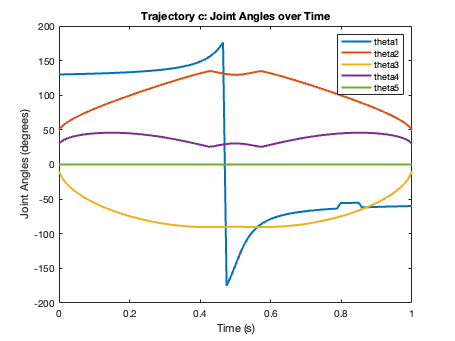



% (2) Plot Joint Angles
figure;
plot(tt-1, joint_trajectory, 'LineWidth', 2);
title(['Trajectory c: Joint Angles over Time']);
xlabel('Time (s)'); ylabel('Joint Angles (degrees)');
legend('theta1', 'theta2', 'theta3', 'theta4', 'theta5');

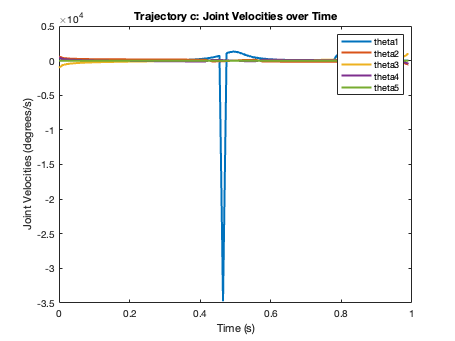


% (3) Calculate and Plot Joint Velocities
joint_velocities = diff(joint_trajectory) / (tt(2) - tt(1));  % Derivative w.r.t time
figure;
ylim([-400, 800]);
plot(tt(1:end-1)-1, joint_velocities, 'LineWidth', 2);
title(['Trajectory c: Joint Velocities over Time']);
xlabel('Time (s)'); ylabel('Joint Velocities (degrees/s)');
legend('theta1', 'theta2', 'theta3', 'theta4', 'theta5');

function collision = isCollisionWithObstacle(start_point, end_point, obstacle_center, obstacle_radius, obstacle_height)
    % 判断路径是否与圆柱体相交
    % start_point 和 end_point 是路径的起始点和终点
    % obstacle_center 是障碍物中心的坐标
    % obstacle_radius 是障碍物的半径
    % obstacle_height 是障碍物的高度
    
    % 计算路径的中点
    mid_point = (start_point + end_point) / 2;
    % 计算路径的垂直距离
    distance = sqrt((mid_point(1) - obstacle_center(1))^2 + (mid_point(2) - obstacle_center(2))^2);
    
    % 如果路径距离障碍物的中心小于圆柱体的半径，说明发生碰撞
    if distance < obstacle_radius && abs(mid_point(3) - obstacle_center(3)) < obstacle_height / 2
        collision = true;
    else
        collision = false;
    end
end



